% Filtro IIR Butterworth - Pasa Banda
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - IIR - Diseño del filtro Pasa Banda**

**Parámetros de diseño**

fm=22418;             % Hz,  Frecuencia de Muestreo
                             
%---------------------------------|--------------------------------------
                     f0=1326;                              
BMAX=2*f0;     
%-------------------|xxxxxxxxxxxxxxxxxxxxxxxxxxx|----------------------------
                 B1=865;  

%--------------------yyy|xxxxxxxxxxxxxxxxxxx|yyyy----------------------------       
            B2=625;  Ap=0.3 ;                
%xxxxxxxx|----------------------------------------------------|xxxxxxxxxx                                                          
     B3=2652;  As=10 ;            

w0=2*pi*f0;
B= 2*pi*B1;
Bp=2*pi*B2;
Bs=2*pi*B3;

**Diseño del filtro**

- Encontrar las frecuencias de borde

syms w;

%  frecuencia de corte (frecuencias de borde)
[s1]=vpasolve(w^2+B*w-w0^2==0,w);
f1=s1(2)/2/pi

$$f1 = 962.2517$$

f2=(B+f1*2*pi)/2/pi

$$f2 = 1.8273e+03$$


%  frecuencias en la banda de paso
[s3]=vpasolve(w^2+Bp*w-w0^2==0,w);
f3=s3(2)/2/pi;
f4=(Bp+f3*2*pi)/2/pi;

% frecuencias en la banda de rechazo
[s5]=vpasolve(w^2+Bs*w-w0^2==0,w);
f5=s5(2)/2/pi;
f6=(Bs+f5*2*pi)/2/pi;

- Transformar las caracteristicas de frecuencia de paso bajo a paso bajo normalizado

Fc=1

Fc =      1


Fp=(f4-f3)/(f2-f1)

$$Fp = 0.7225$$

Fs=(f6-f5)/(f2-f1)

$$Fs = 3.0659$$

- Cálculo del Orden del filtro:

N=mi_butter_orden_lp(Fp, Ap, Fs, As)

$$N = 5$$

- Función de transferencia y respuesta en frecuencia

%[Bs,As]=butter(N, Fc*2*pi, 'low','s');
[BS,AS]=mi_butter(N);
sysS=tf(BS,AS)

sysS =
 
                            1
  -----------------------------------------------------
  s^5 + 3.236 s^4 + 5.236 s^3 + 5.236 s^2 + 3.236 s + 1
 
Continuous-time transfer function.



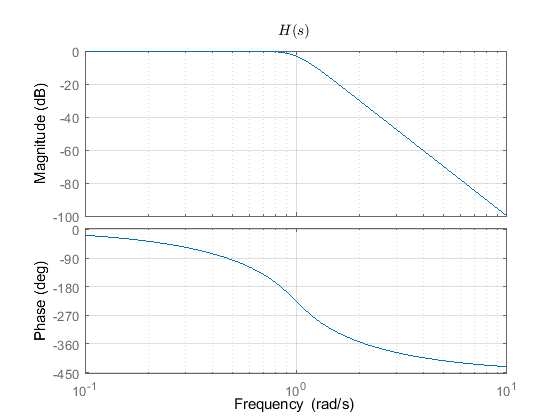

fig0=figure; bode(sysS); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;...
saveas(fig0,'output/stm32_iir_bp_butterworth_0','jpg');

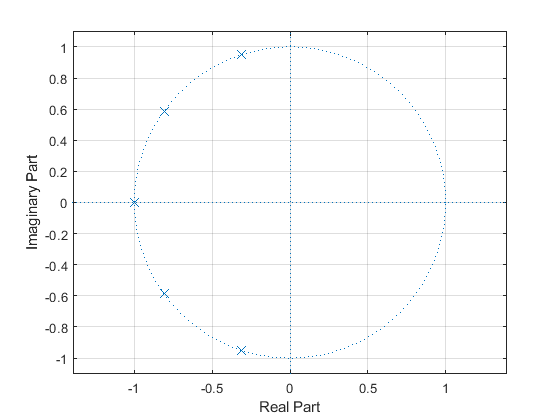

fig1=figure; Np=max(length(BS),length(AS));
zplane( [zeros(1, Np-length(BS)) BS], [  zeros(1, Np-length(AS)) AS] );...
grid on; saveas(fig1,'output/stm32_iir_bp_butterworth_1','jpg');


syms s; ecu_latex = ['H(s)=', latex(poly2sym(BS,s)/poly2sym(AS,s))];
save_ecu('output/stm32_iir_bp_butterworth_ecu_SM.tex', ecu_latex);

- Transformación en frecuencia de paso bajo a paso medio

[Bs, As] = mi_lp2bp(BS,AS, w0, B);
syss=tf(Bs,As)

syss =
 
                                                    
                                        1.614e59 s^5
                                                    
  -----------------------------------------------------------------------------------------
                                                                                           
  3.403e40 s^10 + 5.985e44 s^9 + 1.707e49 s^8 + 1.948e53 s^7 + 2.832e57 s^6 + 2.143e61 s^5 
                                                                                           
                    + 1.966e65 s^4 + 9.385e68 s^3 + 5.71e72 s^2 + 1.389e76 s + 5.484e79    
                                                                                           
 
Continuous-time transfer function.



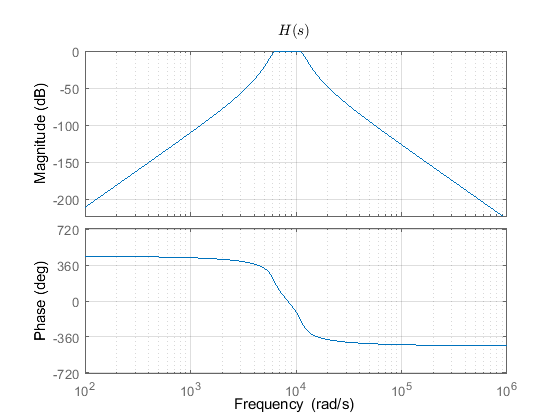

fig2=figure; bode(syss); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;   ...
saveas(fig2,'output/stm32_iir_bp_butterworth_2','jpg');

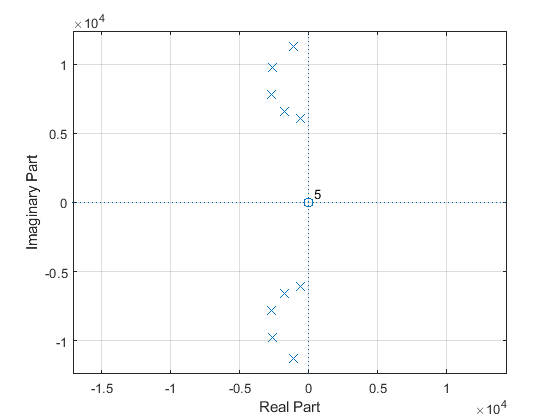

fig3=figure; Np=max(length(Bs),length(As));
zplane( [zeros(1, Np- length(Bs)) Bs  ], [zeros(1, Np- length(As))  As ] ); ...
grid on; saveas(fig3,'output/stm32_iir_bp_butterworth_3','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(Bs,s)/poly2sym(As,s))];
save_ecu('output/stm32_iir_bp_butterworth_ecu_s.tex', ecu_latex);

**Transformación bilinear - matlab.**

mapeo="bilineal(matlab)";

switch mapeo
    case "integracion"
        [Bz, Az]=mi_integral(Bs, As, fm);
    case "invariante al impulso"
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case "invariante(matlab)"
        [Bz, Az]=impinvar(Bs, As, fm);
    case "bilineal"
        [Bz, Az]=mi_bilinear(Bs, As, fm);
    case "bilineal(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm, f0);        
end
m=max( abs([ Bz, Az ]) ); Bz=Bz/m; Az=Az/m;
Bz=Bz/Az(1); Az=Az/Az(1);
sysz=tf(Bz,Az,1/fm,'Variable','z^-1')

sysz =
 
                                                                                       
  1.59e-05 - 3.553e-15 z^-1 - 7.951e-05 z^-2 - 7.105e-14 z^-3 + 0.000159 z^-4          
                                                                                       
          - 1.137e-13 z^-5 - 0.000159 z^-6 - 2.132e-14 z^-7 + 7.951e-05 z^-8           
                                                                                       
                                                      - 1.776e-15 z^-9 - 1.59e-05 z^-10
                                                                                       
  -------------------------------------------------------------------------------------
                                                                                       
  1 - 8.607 z^-1 + 33.91 z^-2 - 80.5 z^-3 + 127.4 z^-4 - 140.5 z^-5 + 109.3 z^-6       
                                                                                       
                       

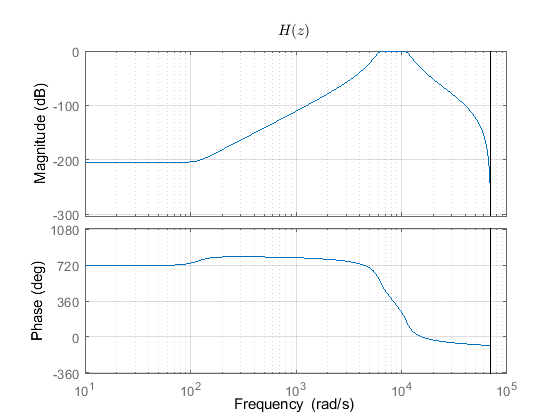

syms z; fig4=figure; bode(sysz); grid on;...
title(sprintf('$$%s$$', 'H(z)'), 'Interpreter','latex');    ...
saveas(fig4, 'output/stm32_iir_bp_butterworth_4', 'jpg');

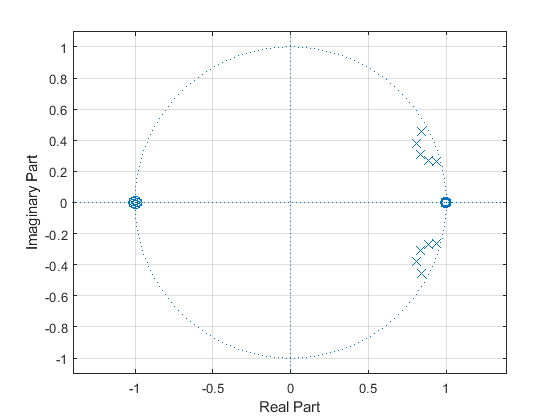

fig5=figure; Np=max( length(Bz),length(Az) );
zplane( [  zeros(1, Np- length(Bz)) Bz], [ zeros(1, Np- length(Az)) Az ] );...
grid on; saveas(fig5,'output/stm32_iir_bp_butterworth_5','jpg');

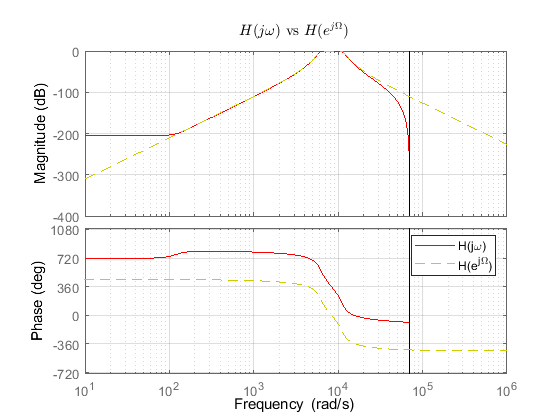

ecu_latex = ['H(z)=', latex(poly2sym(Bz,z)/poly2sym(Az,z))];
save_ecu('output/stm32_iir_bp_butterworth_ecu_z.tex', ecu_latex);

syms z; fig6=figure; bode(sysz,'r',syss,'y--'); grid on;...
title(sprintf('$$%s$$', 'H(j\omega)\mbox{ vs }H(e^{j\Omega})'), 'Interpreter','latex');    ...    
legend( sprintf('%s', 'H(j\omega)'), sprintf('%s', 'H(e^{j\Omega})'));
saveas(fig6,'output/stm32_iir_bp_butterworth_6','jpg');

**Generación de la linea de código para el micrcontrolador - **vector de coeficientes

PRECISION_STM32=8;
stm32_coef=to_stm32(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Buttherworth - Pasa Banda', mapeo); ...
saveImplementacion('output/stm32_iir_bp_butterworth_stm32_coef.txt', stm32_coef); fprintf('%s\n',stm32_coef) 

//Filtro IIR - Buttherworth - Pasa Banda - bilineal(matlab) 
//Orden: 5
//Frecuencia de Muestreo: 22418 (Hz)
#define ORDEN 10
double coef_x[]= {0.00001590,-0.00000000,-0.00007951,-0.00000000,0.00015902, 
			-0.00000000,-0.00015902,-0.00000000,0.00007951,-0.00000000, 
			-0.00001590};
double coef_y[]= {-1.00000000,8.60684135,-33.91205680,80.49757056,-127.42624846, 
			140.52526259,-109.32857281,59.25740441,-21.42019228,4.66518510, 
			-0.46522603};


**Generación de la linea para inicializar el callback de simulink**

simulink_coef=to_simulink(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Butterworth - Pasa Banda', mapeo); ...
saveImplementacion('output/stm32_iir_bp_butterworth_simulink_coef.txt', simulink_coef); ...
    fprintf('%s\n',simulink_coef) 

	%Filtro IIR - Butterworth - Pasa Banda - bilineal(matlab) 
	%Orden: 5
	%Frecuencia de Muestreo: 22418 (Hz)
	Fm=22418;
	ORDEN=5;
	coef_x= [1.5902462e-05,-3.5527137e-15,-7.9512309e-05,-7.1054274e-14,0.00015902462, ...
			-1.1368684e-13-0.00015902462-2.1316282e-147.9512309e-05-1.7763568e-15 ...
			-1.5902462e-05];
	coef_y= [-1,8.6068414,-33.912057,80.497571,-127.42625, ...
			140.52526-109.3285759.257404-21.4201924.6651851 ...
			-0.46522603];




save('output/stm32_iir_pb_butterworth.mat');